# Genetic Algorithm

Inputs:

syms Roulette_Wheel Tournament
N=3;                % Population Size      
L=3;               % Length of Chromosome
P=[1 0 1;0 0 1;1 0 0];
max_iter=3;        % Maximum Iterations
p_c=2/N;            % Crossover
p_m=0.01;           % Mutation
fprintf('Choose Selectrion Criteria:\n')

Choose Selectrion Criteria:


fprintf('Roulette-wheel = 0 \n')

Roulette-wheel = 0 


fprintf('Tournament = 1 \n')

Tournament = 1 


selection=input('Enter the Selection Number: ')

selection = 0

if selection==0
elseif selection==1
else
    disp('Incorrect Number');
    return;
end

Algorithm:

for i=1:N
fitness(i)= feval('fit_func1',P(i,:));
end
bestvaluesofar=0;
[bestvalue,best] = max(fitness)

bestvalue = 158.4922

best = 3

if bestvalue > bestvaluesofar
bestsofar = P(best,:)
bestvaluesofar = bestvalue
end

bestsofar =      1     0     0


bestvaluesofar = 158.4922


for k = 1:max_iter
    fitness = fitness - min(fitness);
    if sum(fitness) == 0
    disp('Population has identical chromosomes -- STOP');
    disp('Number of iterations:');
    disp(k);
    for i = k:max_iter
        upper(i)=upper(i-1);
        average(i)=average(i-1);
        lower(i)=lower(i-1);
    end
    break
    else
        fitness = fitness/sum(fitness);
    end
    if selection==0
        fprintf('Selection Criteria is: %s ',Roulette_Wheel)
    else 
        fprintf('Selection Criteria is: %s',Tournament)
    end
   if selection==0
       %roulette-wheel
       cum_fitness = cumsum(fitness);
       for i = 1:N
           tmp = find(cum_fitness-rand>0);
           m(i) = tmp(1);
       end
   else
       %tournament
       for i = 1:N
           fighter1=ceil(rand*N);
           fighter2=ceil(rand*N);
           fitness;
           fitness(fighter1);
           fitness(fighter2);
           if fitness(fighter1)>fitness(fighter2)
               m(i) = fighter1;
           else
               m(i) = fighter2;
           end
       end
   end
   M = zeros(N,L);
   for i = 1:N
       M(i,:) = P(m(i),:);
   end
   
   %Crossover
   Mnew = M
   for i = 1:N/2
       ind1 = ceil(rand*N);
       ind2 = ceil(rand*N);
       parent1 = M(ind1,:);
       parent2 = M(ind2,:);
       if rand < p_c
           crossover_pt = ceil(rand*(L-1));
           offspring1 = [parent1(1:crossover_pt) parent2(crossover_pt+1:L)];
           offspring2 = [parent2(1:crossover_pt) parent1(crossover_pt+1:L)];
           Mnew(ind1,:) = offspring1;
           Mnew(ind2,:) = offspring2;
       end
   end
   
   %Mutation
   mutation_points = rand(N,L) < p_m;
   P = xor(Mnew,mutation_points);
   
   %Evaluation
    for i = 1:N
        fitness(i) = feval('fit_func1',P(i,:));
    end
    [bestvalue,best] = max(fitness);
    if bestvalue > bestvaluesofar
        bestsofar = P(best,:)
        bestvaluesofar = bestvalue
    end
    upper(k) = bestvalue;
    average(k) = mean(fitness);
    lower(k) = min(fitness);
end

Selection Criteria is: Roulette_Wheel 

Mnew =      1     0     1
     1     0     0
     1     0     1


Selection Criteria is: Roulette_Wheel 

Mnew =      1     0     0
     1     0     0
     1     0     0


Population has identical chromosomes -- STOP


Number of iterations:


     3



Plot

if k == max_iter
disp('Algorithm terminated after maximum number of iterations:');
disp(max_iter);
end

Algorithm terminated after maximum number of iterations:


     3



winner = bestsofar

winner =      1     0     0


bestfitness = bestvaluesofar

bestfitness = 158.4922

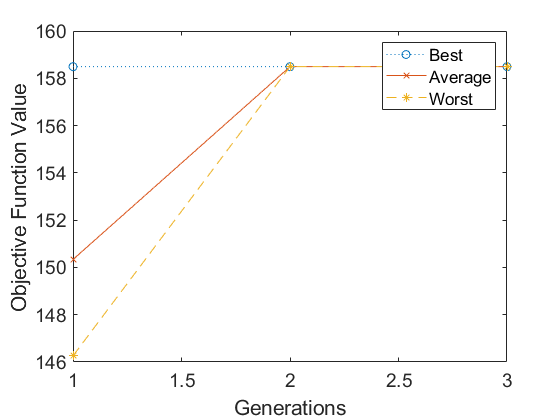

if k == k
iter = [1:max_iter]';
plot(iter,upper,'o:',iter,average,'x-',iter,lower,'*--')
legend('Best', 'Average', 'Worst')
xlabel('Generations','Fontsize',14)
ylabel('Objective Function Value','Fontsize',14)
set(gca,'Fontsize',14)
hold off
end

Functions Used:

function y=f_manymax(x)
y=-15*(sin(2*x))^2-(x-2)^2+160;         % Change Function Accordingly
end

function dec = bin2dec(bin,range) 
%function dec = bin2dec(bin,range);
%Function to convert from binary (bin) to decimal (dec) in a given range
index = polyval(bin,2);  
dec = index*((range(2)-range(1))/(2^length(bin)-1)) + range(1); 
end

function y=fit_func1(binchrom)
%1-D fitness function
f='f_manymax';
range=[-10,10];                     % Change Range Accordingly
x=bin2dec(binchrom,range);
y=feval(f,x);
end